clc; clear; close all;

%% --- Step 1: Load Wind Data ---
A = importdata('31Oct2024.dat');
wind_speed = A.data(:,1);  % assuming wind speed in column 1

% Clean data: remove NaNs and negatives
valid_idx = ~isnan(wind_speed) & wind_speed > 0;
wind_clean = wind_speed(valid_idx);

fs = 10;  % Sampling frequency in Hz

%% --- Step 2: Compute Realistic PSD from Data (Welch method) ---
[PSD_real, f_real] = pwelch(wind_clean - mean(wind_clean), ...
                            hamming(1024), 512, 1024, fs, 'onesided');

%% --- Step 3: Davenport PSD Parameters ---
U_mean = 3.15;       % Mean wind speed (m/s)
sigma_u = std(wind_clean); % Std deviation from real data
L = 120;             % Turbulence length scale (m)
f = logspace(-3, 1, 200); % Frequency range (Hz)

% Davenport formula
Sv = (4 * sigma_u^2 * L / U_mean) ./ ...
     (1 + 6*f*L/U_mean).^(5/3);

%% --- Step 4: Transfer Function H(s) ---
s = tf('s');
H = (0.72*s^4 - 862.5*s^2 + 1.402e4) / ...
    (s^4 - 221*s^2 + 312.2);

% Compute |H(jw)|^2
w = 2*pi*f;  
[mag, ~] = bode(H, w);
mag = squeeze(mag);
PSD_from_H = mag.^2; % For unit variance white noise input

%% --- Step 5: Find Best α to Fit PSD_from_H to Davenport over all f ---
alpha = (Sv(:)' * PSD_from_H(:)) / (PSD_from_H(:)' * PSD_from_H(:));
PSD_from_H_scaled = alpha * PSD_from_H;

%% --- Step 6: Show Transfer Functions ---
disp('Transfer Function for unit variance white noise input:')

Transfer Function for unit variance white noise input:


H

H =
 
  0.72 s^4 - 862.5 s^2 + 14020
  ----------------------------
     s^4 - 221 s^2 + 312.2
 
Continuous-time transfer function.
Model Properties



% Scaling TF output by sqrt(alpha) so that its PSD matches best-fit scaling
H_scaled = sqrt(alpha) * H;
disp('Best-fit scaled Transfer Function:')

Best-fit scaled Transfer Function:


H_scaled

H_scaled =
 
  0.1083 s^4 - 129.7 s^2 + 2108
  -----------------------------
      s^4 - 221 s^2 + 312.2
 
Continuous-time transfer function.
Model Properties


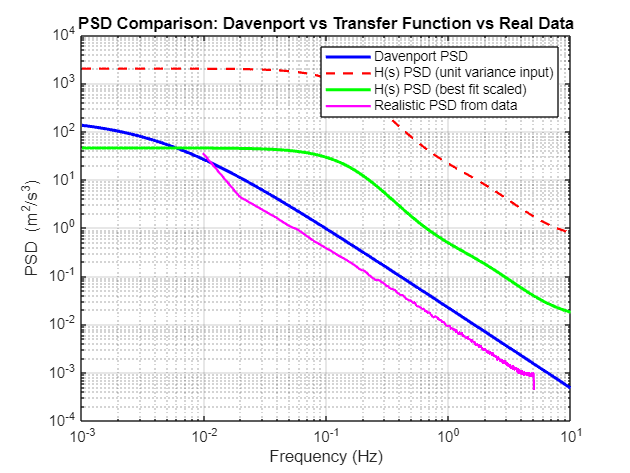


%% --- Step 7: Plot Comparison ---
figure;
loglog(f, Sv, 'b', 'LineWidth', 2); hold on;
loglog(f, PSD_from_H, 'r--', 'LineWidth', 1.5);
loglog(f, PSD_from_H_scaled, 'g', 'LineWidth', 2);
loglog(f_real, PSD_real, 'm', 'LineWidth', 1.5);
grid on;
xlabel('Frequency (Hz)');
ylabel('PSD (m^2/s^3)');
legend('Davenport PSD', ...
       'H(s) PSD (unit variance input)', ...
       'H(s) PSD (best fit scaled)', ...
       'Realistic PSD from data');
title('PSD Comparison: Davenport vs Transfer Function vs Real Data');






%% Continuous-time transfer function
num_ct = [0.1083 0 -129.7 0 2108];    % s^4 ... s^0
den_ct = [1 0 -221 0 312.2];

Hc = tf(num_ct, den_ct);

%% Choose sampling time
Ts = 0.01;   % seconds (adjust as needed)

%% Discretize using bilinear (Tustin) method
Hd = c2d(Hc, Ts, 'tustin');

%% Display discrete transfer function
disp('Discrete-time transfer function (bilinear method):');

Discrete-time transfer function (bilinear method):


Hd

Hd =
 
  0.1056 z^4 - 0.4356 z^3 + 0.6599 z^2 - 0.4356 z + 0.1056
  --------------------------------------------------------
         z^4 - 4.022 z^3 + 6.044 z^2 - 4.022 z + 1
 
Sample time: 0.01 seconds
Discrete-time transfer function.
Model Properties



%% Extract numerator, denominator
[num_d, den_d] = tfdata(Hd, 'v');

%% Poles and zeros
[z_d, p_d, k_d] = zpkdata(Hd, 'v');

disp('Discrete-time poles:');

Discrete-time poles:


disp(p_d);

    1.1600
    1.0120
    0.9881
    0.8620



disp('Discrete-time zeros:');

Discrete-time zeros:


disp(z_d);

    1.4150
    1.0414
    0.9602
    0.7067




%% Convert to state-space
sysd = ss(Hd);
A = sysd.A; 
B = sysd.B; 
C = sysd.C; 
D = sysd.D;

%% Stability check (all poles inside unit circle)
isStable = all(abs(p_d) < 1);
disp(['Is system stable? ', string(isStable)]);

    "Is system stable? "    "false"




%% Output variance for unit-variance white noise input
% Only valid if system is stable
if isStable
    % Solve discrete Lyapunov equation: A P A' - P + B B' = 0
    P = dlyap(A, B*B');
    sigma_y2 = C * P * C' + D*D';
    disp('Output variance for unit-variance white noise input:');
    disp(sigma_y2);
else
    warning('System is unstable, output variance not computed.');
end

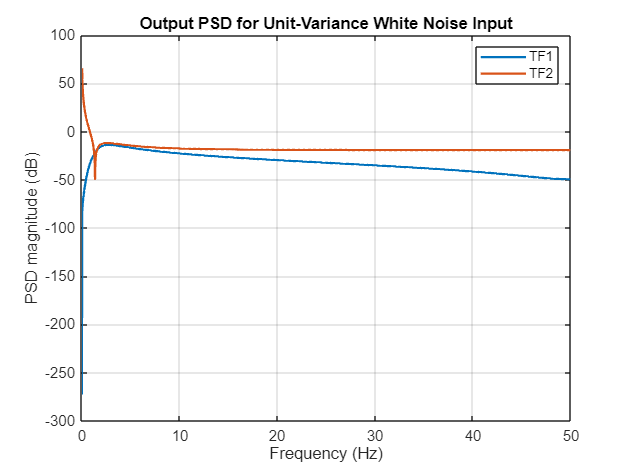



%% First TF
num1 = [0.02679  -0.05951  0.01895  0.03348  -0.01971];
den1 = [1  -3.952  5.857  -3.857  0.9523];
Ts1 = 0.01;

Hd1 = tf(num1, den1, Ts1);

%% Second TF
num2 = [0.1056  -0.4356  0.6599  -0.4356  0.1056];
den2 = [1  -4.022  6.044  -4.022  1];
Ts2 = 0.01;

Hd2 = tf(num2, den2, Ts2);

%% Frequency response (magnitude squared = PSD for white noise input)
nfft = 2048;   % number of frequency points
[H1, w] = freqz(num1, den1, nfft, 1/Ts1);   % w in Hz
H2 = freqz(num2, den2, nfft, 1/Ts2);

PSD1 = abs(H1).^2;   % output PSD
PSD2 = abs(H2).^2;

%% Plot
figure;
plot(w, 10*log10(PSD1), 'LineWidth', 1.5); hold on;
plot(w, 10*log10(PSD2), 'LineWidth', 1.5);
grid on;
xlabel('Frequency (Hz)');
ylabel('PSD magnitude (dB)');
title('Output PSD for Unit-Variance White Noise Input');
legend('TF1', 'TF2');